clear all 
close all 
clc 

## Experiment 1 - Gyroscope Starts in Equilibrium Orientation

Experiment 1 - Gyroscope Starts in Equilibrium Orientation


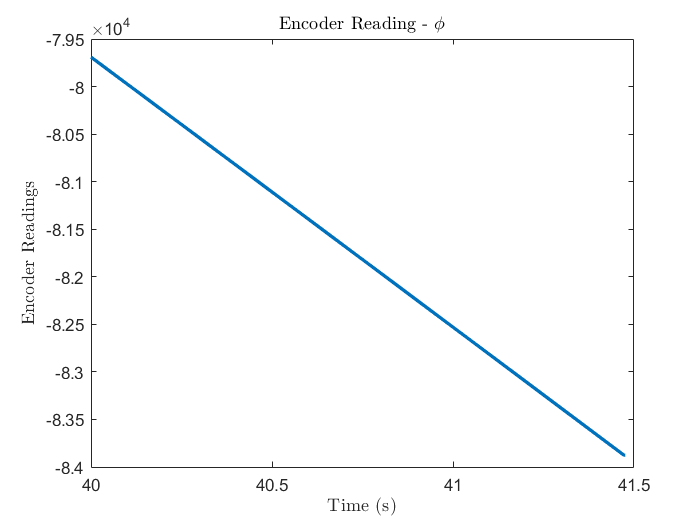

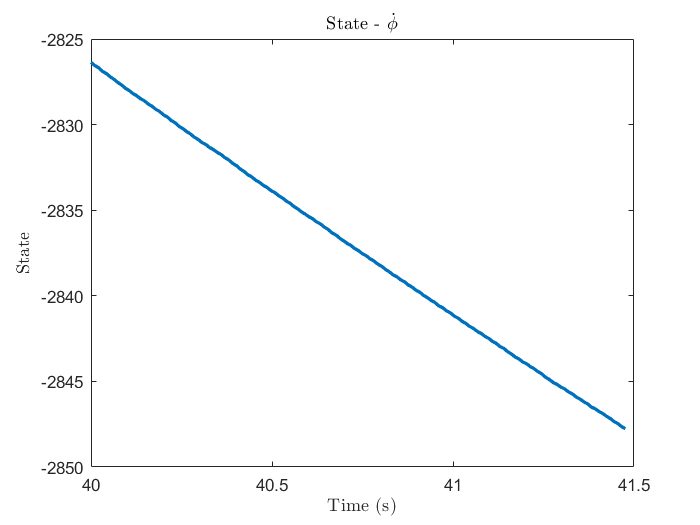

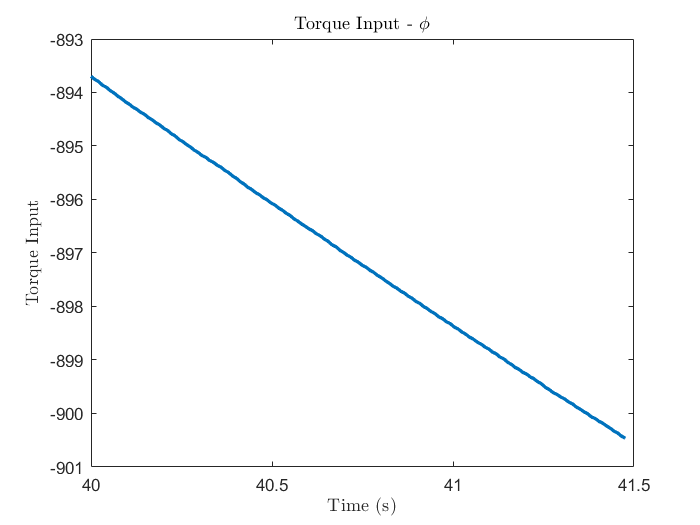

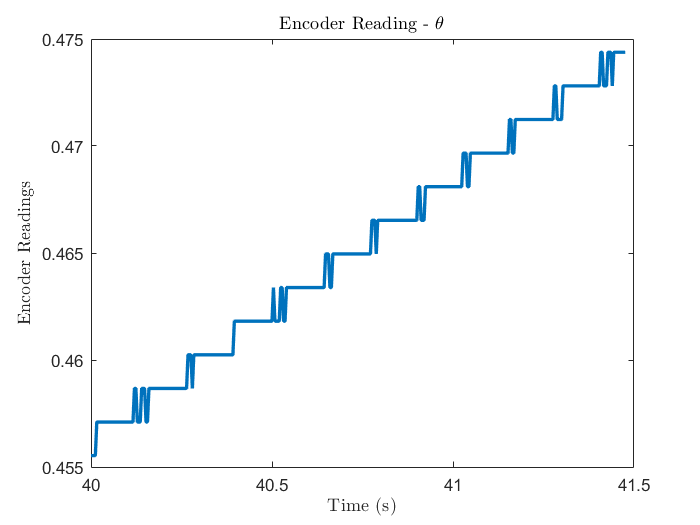

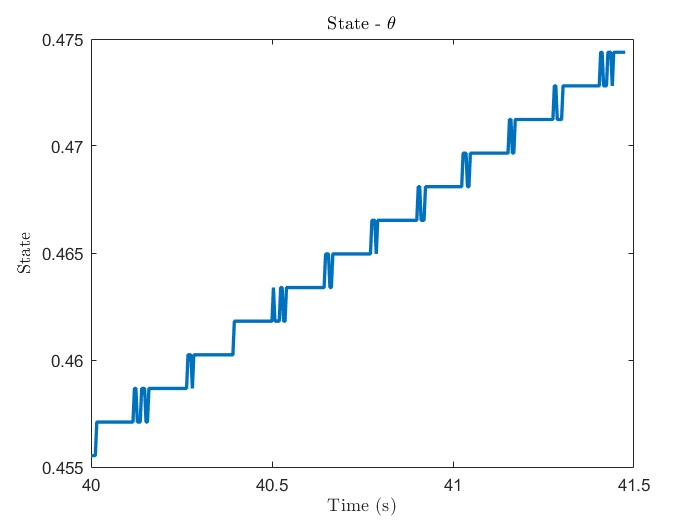

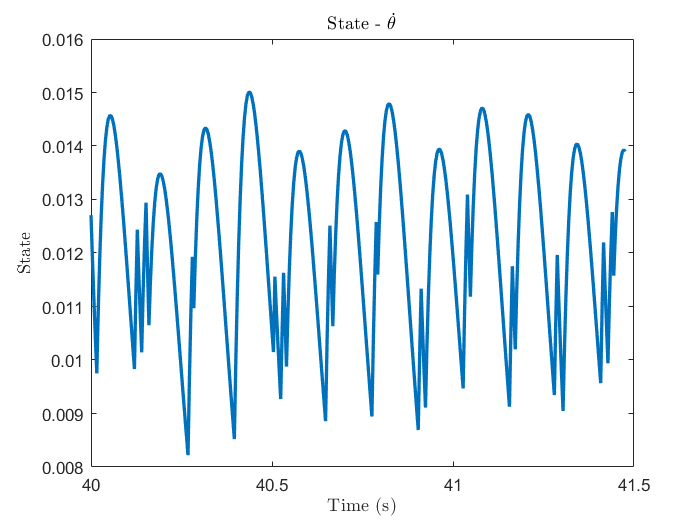

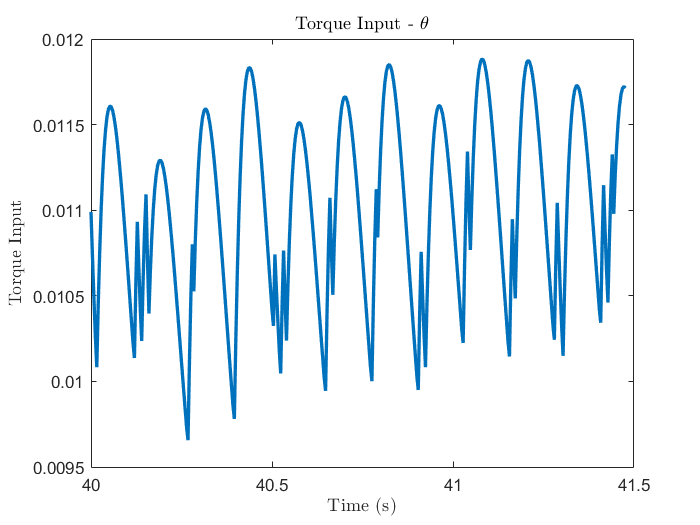

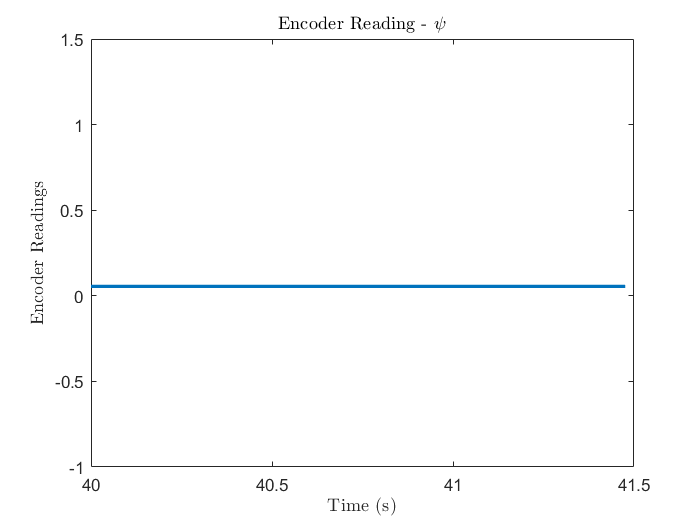

generate_plots('exp1-00.mat','Experiment 1 - Gyroscope Starts in Equilibrium Orientation')

Experiment 2 - Initial Non-Zero PSI


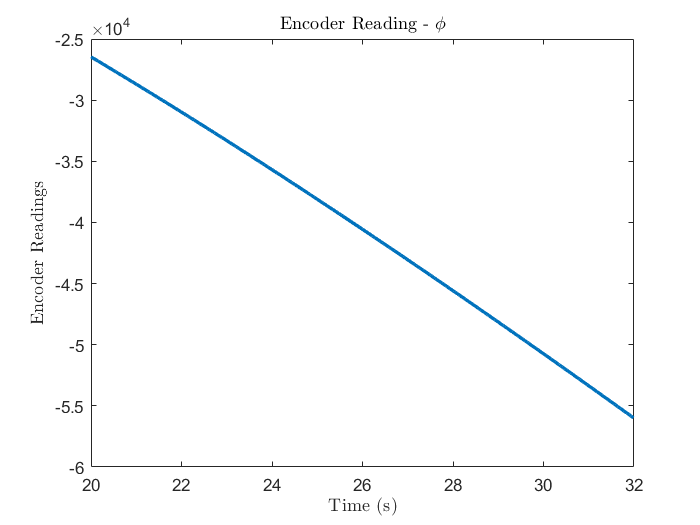

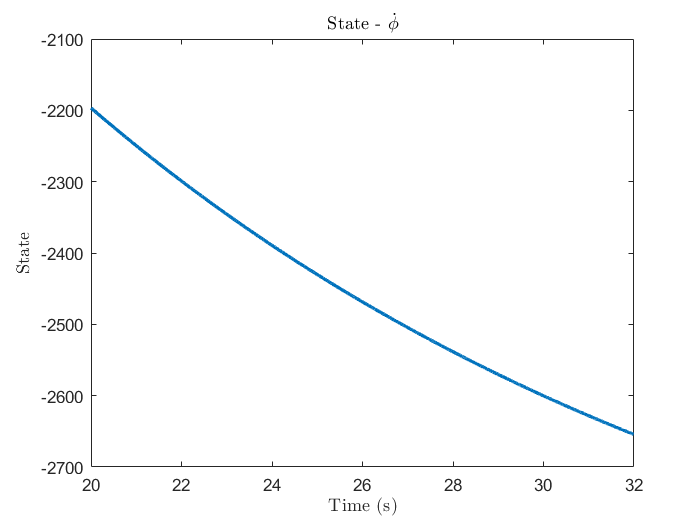

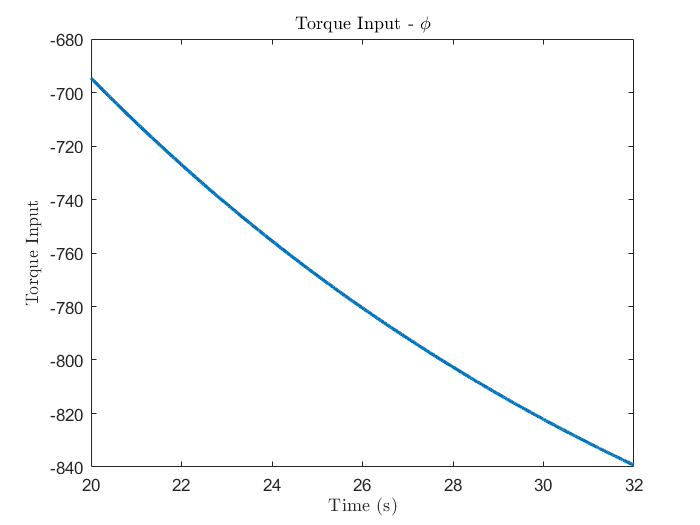

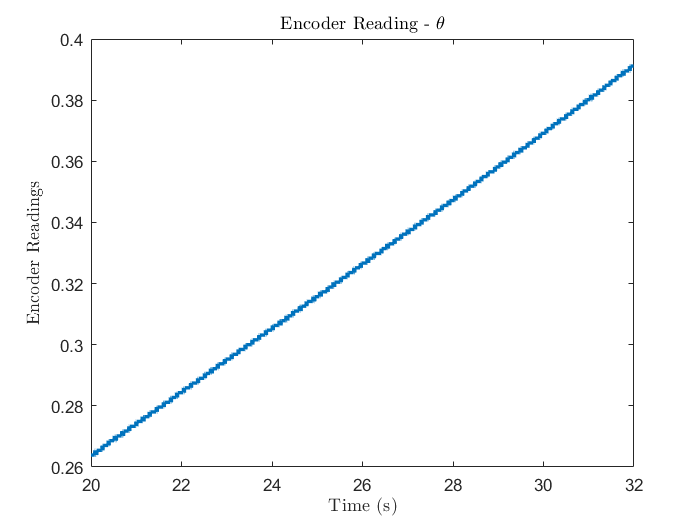

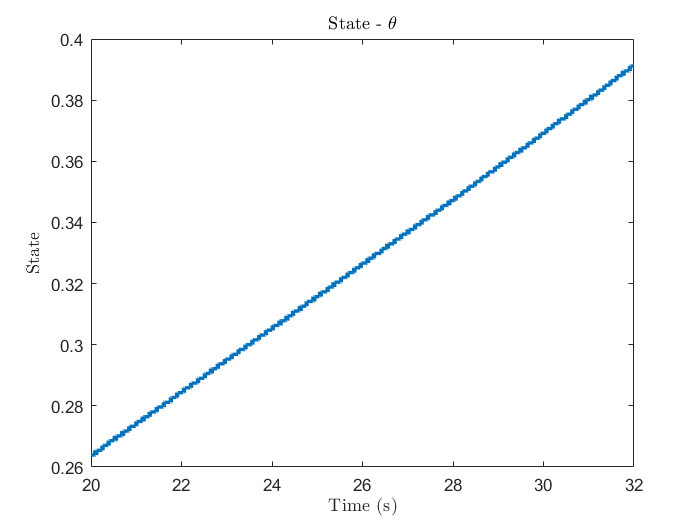

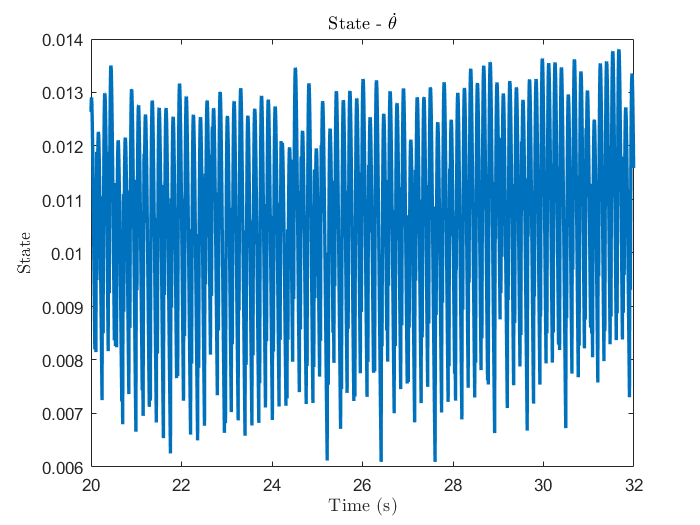

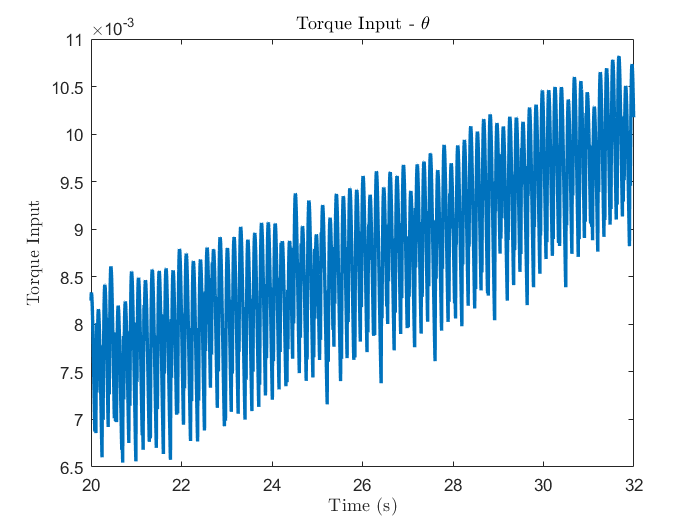

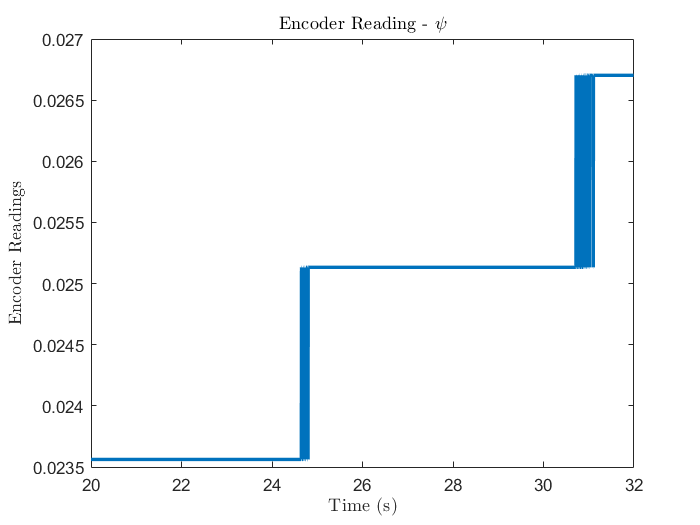


generate_plots('exp2-psi.mat','Experiment 2 - Initial Non-Zero PSI')

function generate_plots(file_name,disp_title)
    disp(disp_title);
    load(file_name,'encoder_reading','Psi_tau','theta_tau','phi_tau','states');
   
    grapher(encoder_reading(:,1),encoder_reading(:,2),'Encoder Reading - $\phi$','Time (s)','Encoder Readings')
    grapher(states.time,states.signals.values(:,3),'State - $\dot{\phi}$','Time (s)','State')
    grapher(phi_tau(:,1),phi_tau(:,2),'Torque Input - $\phi$','Time (s)','Torque Input')    
    
    grapher(encoder_reading(:,1),encoder_reading(:,3),'Encoder Reading - $\theta$','Time (s)','Encoder Readings')
    grapher(states.time,states.signals.values(:,5),'State - $\theta$','Time (s)','State')    
    grapher(states.time,states.signals.values(:,2),'State - $\dot{\theta}$','Time (s)','State')
    grapher(theta_tau(:,1),theta_tau(:,2),'Torque Input - $\theta$','Time (s)','Torque Input')    
    
    
    grapher(encoder_reading(:,1),encoder_reading(:,4),'Encoder Reading - $\psi$','Time (s)','Encoder Readings')
    grapher(states.time,states.signals.values(:,4),'State - $\psi$','Time (s)','State')    
    grapher(states.time,states.signals.values(:,1),'State - $\dot{\psi}$','Time (s)','State')
    grapher(Psi_tau(:,1),Psi_tau(:,2),'Torque Input - $\psi$','Time (s)','Torque Input')
    
end

function grapher(t,y,plot_title,x_label,y_label)
    figure
    plot(t,y,'LineWidth',2)
    hold on
    title(plot_title, 'interpreter','latex')
%     legend('$\dot{\psi}$','$\dot{\theta}$','$\dot{\phi}$','$\theta$','$\psi$', 'interpreter','latex' )
    xlabel(x_label, 'interpreter','latex')
    ylabel(y_label, 'interpreter','latex')
    hold off
end